# Obserevers Design

JJRATH- Feb2021 Open Loop Observer Design

%--------------------------
%----------------------------
% Ex1: Active Suspension System
% qcar_CT = SISO_Nom_Suspension; % The nominal suspension model
qcar_CT = SISO_Dis_suspension; % The disturbed suspension model
t = 0:.01:10-0.01;
% For state feedback control all states are required. % Lets design observer to estimate the states
%---- Open Loop Observer
A_ol=[qcar_CT.a ,zeros(size(qcar_CT.a)); 
       zeros(size(qcar_CT.a)) qcar_CT.a];
B_ol=[qcar_CT.b;qcar_CT.b(:,1),qcar_CT.b(:,2)*0]; % Note that the observer does not have information of disturbance
C_ol=[qcar_CT.c zeros(size(qcar_CT.c));
     zeros(size(qcar_CT.c)) qcar_CT.c];
D_ol=zeros(2,2);
%--- Open Loop Observer and System
OLo_qcarCT = ss(A_ol,B_ol,C_ol,D_ol); % Open loop Observer system

## Simulate Estimation Performance for the Nominal System (i.e. No Road

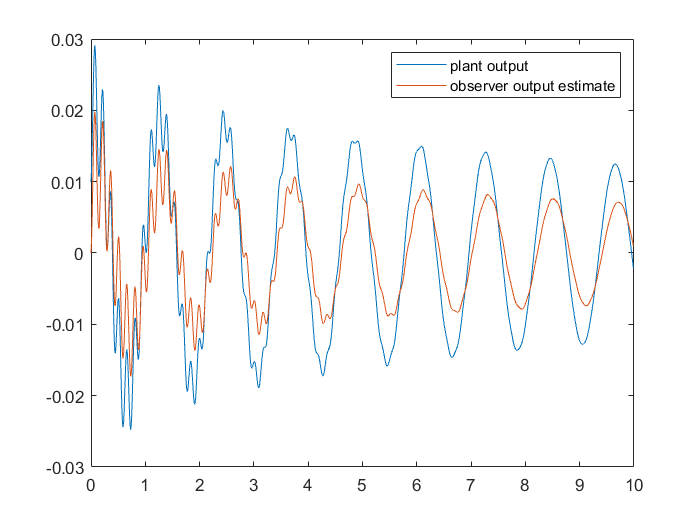

%disturbance)
u_f = 0.1*ones(1,length(t)); % Nominal input of magnitude 0.1
xp = [0.01 0.1 0.5 .1]'; % Initial conditions are  non- zero.
xO = [0 0.1 0.5 .1]';
[Y_OLO,t,X_OLO] = lsim(OLo_qcarCT,[u_f; u_f*0],t,[xp;xO]);
%--------------
figure;
plot(t,X_OLO(:,1),t,X_OLO(:,5)) % first state of the observer is the position of the mass
legend('plant output','observer output estimate')

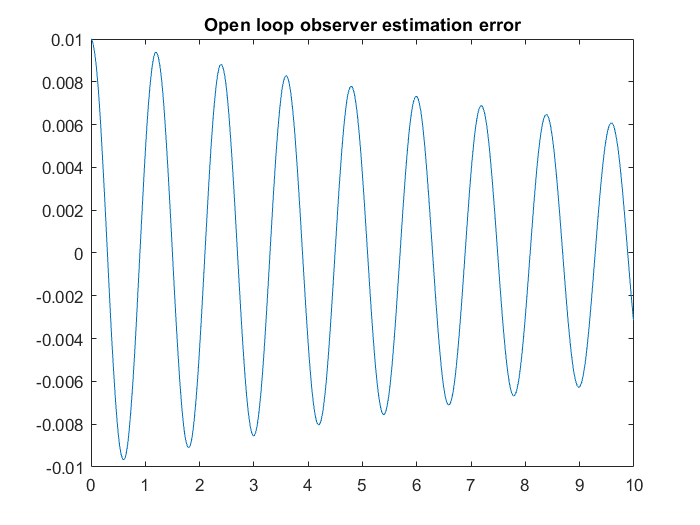

figure;
plot(t,X_OLO(:,1)-X_OLO(:,5)); 
title('Open loop observer estimation error')

## Simulate Estimation Performance for the Distrubed System (i.e. Road

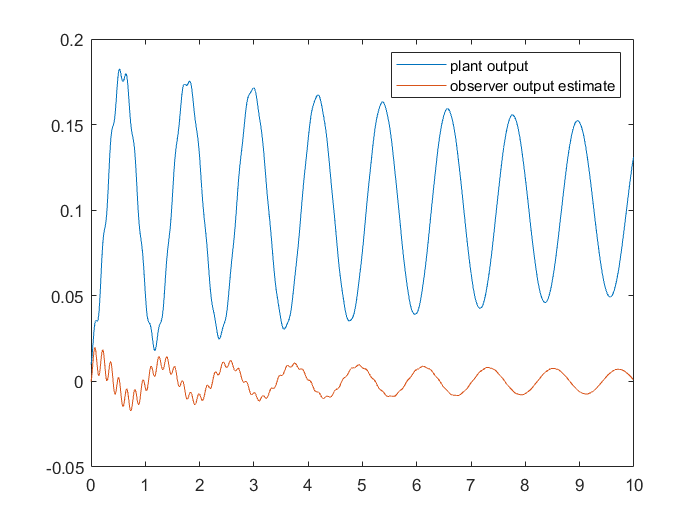

%disturbance) % NOte that observer has no information of distrurbance
u_f = 0.1*ones(1,length(t)); % Nominal input of magnitude 0.1
xp = [0.01 0.1 0.5 .1]'; % Initial conditions are  non- zero.
xO = [0 0.1 0.5 .1]';
[Y_OLO,t,X_OLO] = lsim(OLo_qcarCT,[u_f; u_f],t,[xp;xO]);
%--------------
figure;
plot(t,X_OLO(:,1),t,X_OLO(:,5)) % first state of the observer is the position of the mass
legend('plant output','observer output estimate')

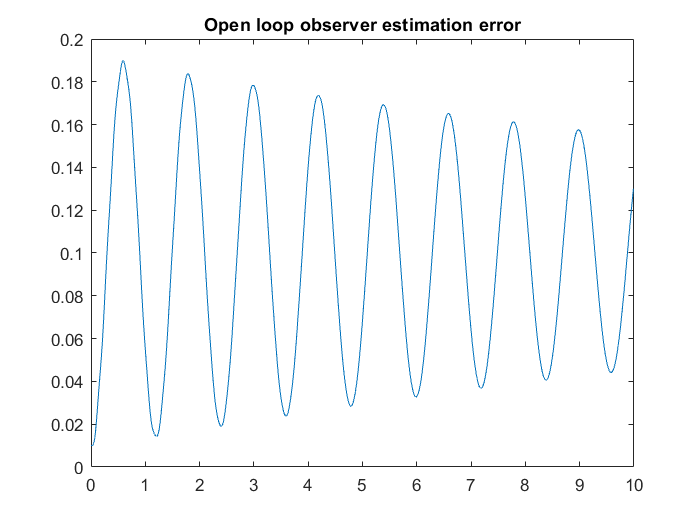

figure;
plot(t,X_OLO(:,1)-X_OLO(:,5)); 
title('Open loop observer estimation error')